%https://www.mathworks.com/help/matlab/ref/fft.html

Fs = 1000; % Sampling freq                  
T = 1/Fs;                    
L = 8000; % signal length
t = (0:L-1)*T; % Time
%t= 0:0.001:8
%Task i)

v_t = abs(sin(pi*t)) + 2*sin(3*pi*t) + 3*sin(6*pi*t)

v_t =          0    0.0785    0.1571    0.2355    0.3139    0.3922    0.4705    0.5485    0.6265    0.7042    0.7818    0.8591    0.9362    1.0131    1.0896    1.1659    1.2418    1.3174    1.3926    1.4675    1.5419    1.6159    1.6895    1.7626    1.8352    1.9073    1.9789    2.0499    2.1204    2.1903    2.2596    2.3282    2.3963    2.4636    2.5303    2.5963    2.6616    2.7261    2.7899    2.8530    2.9152    2.9767    3.0373    3.0972    3.1561    3.2143    3.2715    3.3279    3.3833    3.4379


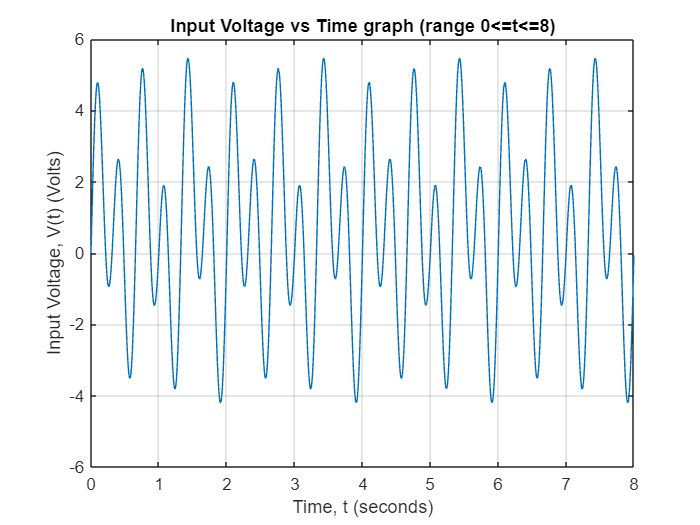

plot(t,v_t)
xlabel('Time, t (seconds)')
ylabel('Input Voltage, V(t) (Volts)')
grid on
title('Input Voltage vs Time graph (range 0<=t<=8)')


%task ii)
v_f = fft(v_t)

v_f = 1.0e+04 *

   0.5093 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.1698 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.8000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0340 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0146 - 1.2000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0081 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0051 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0036 + 0.0000i   0.0000 - 0.0000i


%plot(Fs/L*(0:L-1),abs(v_f),"LineWidth",3)
%plot(Fs/L*(-L/2:L/2-1),abs(fftshift(v_f)),"LineWidth",3)
f = 1:8000

f =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


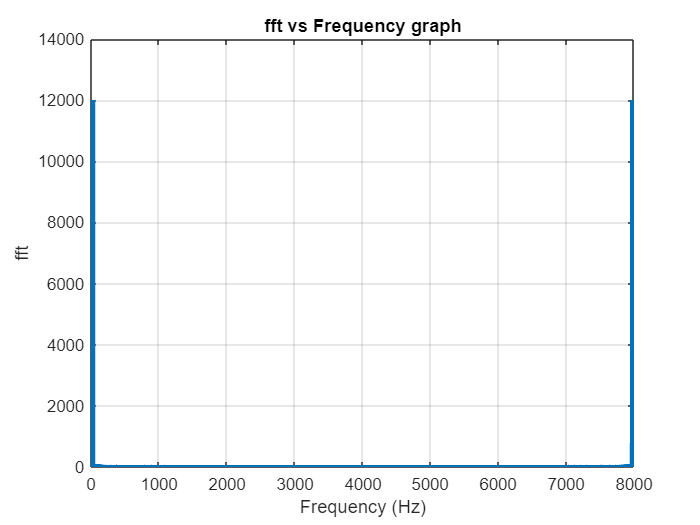

plot(f,abs(v_f),"LineWidth",3)
xlabel('Frequency (Hz)')
ylabel('fft')
grid on
title('fft vs Frequency graph')